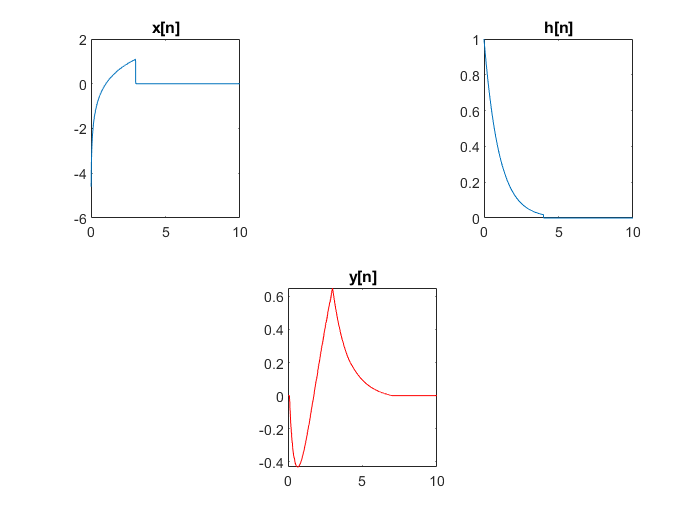

clc  
clear
close all
t=0:0.01:10;
x=log(t).*rect(t,0,3,1);
subplot(2,3,1);plot(t,x);title('x[n]');
h=exp(-t).*(rect(t,0,4,1));
subplot(2,3,3);plot(t,h);title('h[n]');
tau=0.1:0.01:20;
x_tau=log(tau).*rect(tau,0,3,1);
for i=1:length(t)
    tt=t(i);
    h_tau=exp(-1*(tt-tau)).*rect(tt-tau,0,4,1); 
    y(i)=trapz(tau,x_tau.*h_tau);
end 
subplot(2,3,5);plot(t,y,"Color",'r');title('y[n]');